# Unit Testing

The goal is to test the graphical App of the Parking Meter system.

## 1. Clean Session

Clear all remaining variables, figures and timers:

clear variables; close all; clc;
try
  stop(timerfind);
  delete(timerfind);
catch
  disp('No timers are running.');
end

No timers are running.


Add needed classes to the import list:

import matlab.unittest.TestRunner;
import matlab.unittest.TestSuite;
import matlab.unittest.plugins.TestReportPlugin;
import matlab.unittest.plugins.CodeCoveragePlugin;

## 2. Test Runner and Test Suite

Build test runner and test suite allowing to customize how the suite is run and which tests to run.

runner = TestRunner.withTextOutput;

Test report:

reportName = 'Report';
reportType = 'docx';
reportPlugin = TestReportPlugin.producingDOCX([reportName '.' reportType],...
               'IncludingPassingDiagnostics',true,'IncludingCommandWindowText',true); 
runner.addPlugin(reportPlugin);

Coverage report:

coveragePlugin = CodeCoveragePlugin.forFile('..\Component\ParkingMeterGUI.mlapp');
runner.addPlugin(coveragePlugin);

Create the test suite from the defined test class

classSuite = TestSuite.fromClass(?TestApp);

## 3. Initialization

Preparing the parking meter system for the tests:

global UNIT_TESTING;
% Set to true if the MATLAB unit testing API is used, otherwise always false
UNIT_TESTING = true;
% Close any potential running instance of the low-level application
if (system('taskkill /F /im ParkingMeterProject.exe /im cmd.exe &') ~= 0)
  fprintf('No running instance of the low-level application has been detected.\n');
end

No running instance of the low-level application has been detected.


% Call the low-level MATLAB code of the application in a separate process
fprintf('Starting the low-level application instance...\n');

Starting the low-level application instance...


system('..\\Component\\UnitTesting\\ParkingMeterProject.exe&');

## 4. Run Tests

Running TestApp


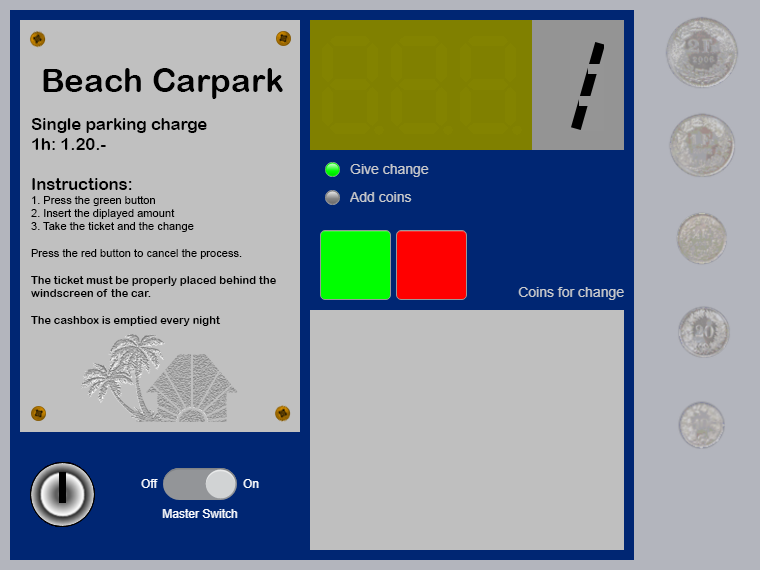

. Processing the test case #1...



Verification failed in TestApp/testCase_1_StraightTicketPurchase.
    ---------------------
    Framework Diagnostic:
    ---------------------
    verifyEqual failed.
    --> Sizes do not match.
        
        Actual size:
             6     2
        Expected size:
             7     2
    
    Actual Value:
      6×2 cell array
    
        {'DISP'}    {'COIN'}
        {'---' }    {' '   }
        {'1.20'}    {' '   }
        {' '   }    {'0.20'}
        {' '   }    {'0.10'}
        {'---' }    {' '   }
    Expected Value:
      7×2 cell array
    
        {'DISP'}    {'COIN'}
        {'---' }    {' '   }
        {'1.20'}    {' '   }
        {' '   }    {'0.50'}
        {' '   }    {'0.20'}
        {' '   }    {'0.10'}
        {'---' }    {' '   }
    ------------------
    Stack Information:
    ------------------
    In D:\GitHub\C_Code_Integration\MATLAB\Component\UnitTesting\TestApp.m (TestApp.ou

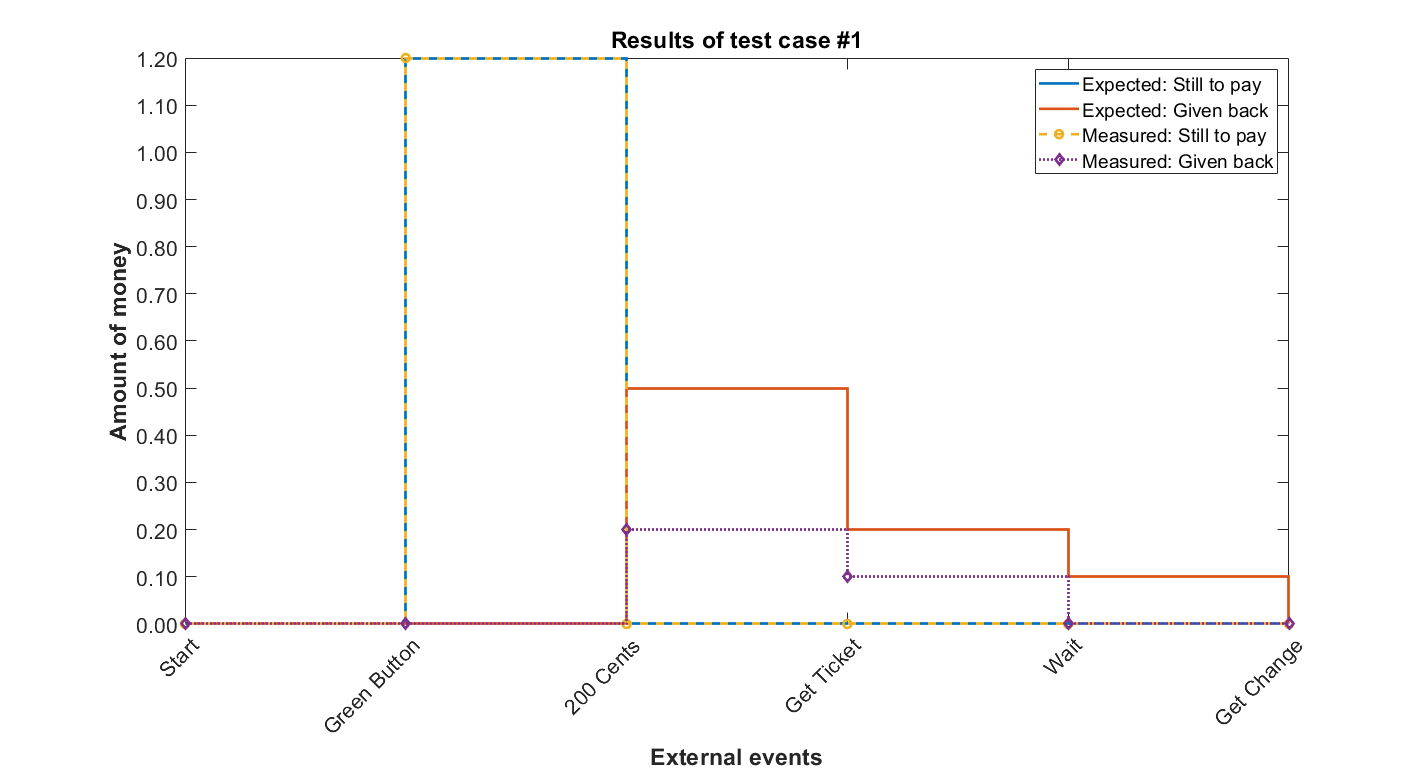


[Terse] Diagnostic logged (2021-02-04 18:56:55):
Figure saved to:
--> C:\Users\sebas\AppData\Local\Temp\50892e71-ec64-4b04-9251-2258473e34cc\Figure_7d7b48c2-6513-408d-89a8-b19f6181538c.fig
--> C:\Users\sebas\AppData\Local\Temp\50892e71-ec64-4b04-9251-2258473e34cc\Figure_7d7b48c2-6513-408d-89a8-b19f6181538c.png
.
Done TestApp
__________

Failure Summary:

     Name                                       Failed  Incomplete  Reason(s)
     TestApp/testCase_1_StraightTicketPurchase    X                 Failed by verification.
Generating test report. Please wait.
    Preparing content for the test report.


    Adding content to the test report.
    Writing test report to file.
Test report has been saved to:
 D:\GitHub\C_Code_Integration\MATLAB\Work\Report.docx
Code coverage report has been saved to:
 C:\Users\sebas\AppData\Local\Temp\tpb4c0764b_3feb_4079_866d_f9904fd87191\index.html


% Call the unit testing framework for automated testing
results = runner.run(classSuite);

% Close the running instance of the low-level application
system('taskkill /F /im ParkingMeterProject.exe /im cmd.exe &');

## 5. Results Summary

disp(results.table);

                        Name                         Passed    Failed    Incomplete    Duration      Details   
    _____________________________________________    ______    ______    __________    ________    ____________

    {'TestApp/testCase_1_StraightTicketPurchase'}    false     true        false        27.951     {1×1 struct}

